Выбираем числа $a,t_1 ,t_2$ , что $t_1 <t_2$. 

Берём функцию g, что 


$$g\left(t\right)=\left\lbrace \begin{array}{ll}
a & t\in \left\lbrack t_1 ,t_2 \right\rbrack \\
0 & ,\textrm{else}
\end{array}\right.$$


% Задайте значения параметров a, t1 и t2
a = 3;
t1 = -2;
t2 = 4;

Теперь возьмём большой интервал времени $T$ и маленький шаг дискретизации $\textrm{dt}$

T = 20;
dt = 0.01;
% Создайте диапазон значений t
t=-T/2:dt:T/2;

Найдём зашумлённую версию сигнала как


$$u=g+b*\left(\textrm{rand}\left(\textrm{size}\left(t\right)\right)-0\ldotp 5\right)+c*\sin \left(d*t\right);$$


% зададим дополнительные коэффиценты - на рандом пока что
b = 1; 
c = 0; 
d = 0;

Построим график фильтра

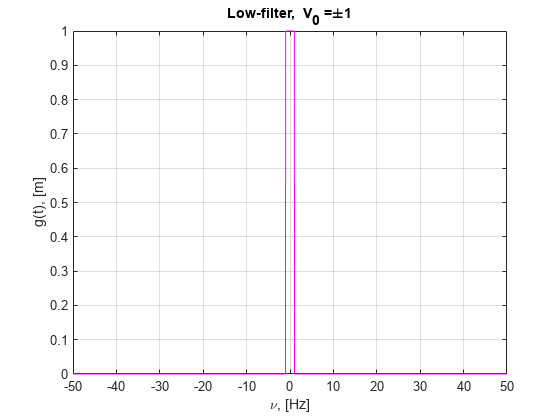

V = 1/dt; % Ширина диапазона частот
dv = 1/T; % Шаг частоты 
v = -V/2 : dv : V/2; % Набор частот для FFT
% Зададим диапазон чистки --> [-V0; V0]
V0 = T/20;
V1 = T/10;
plotFilter(1, v, V0,V1, a);

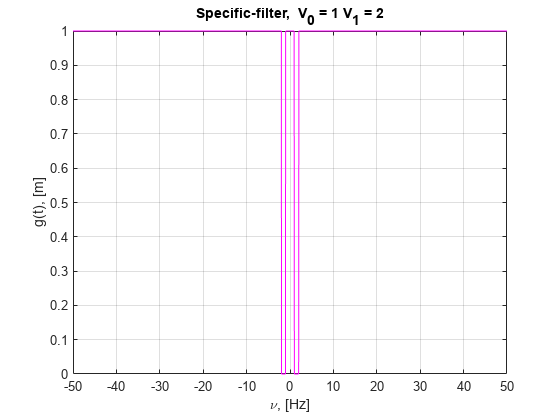

plotFilter(2, v, V0,V1, a);

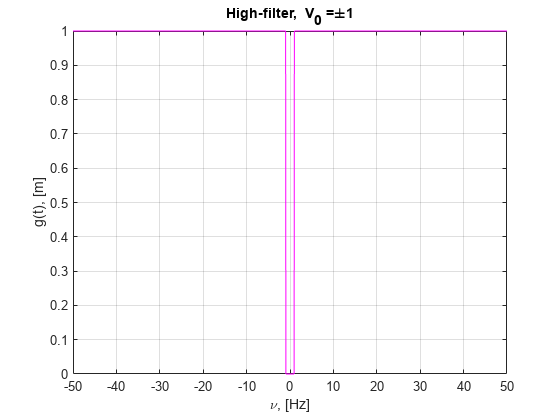

plotFilter(3, v, V0,V1, a);

Получим зашумлённый сигнал и его образ ниже

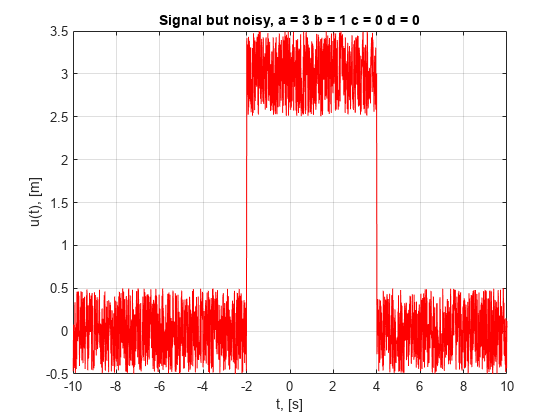

u = g(t,a,t1,t2) + b*(rand(size(t))-0.5) + c*sin(d*t);
U = fftshift(fft(u)); % Прямое преобразование (быстрое)
plotSignal(1, t, t1,t2, a,b,c,d)

Давайте ограничим область видимых частот, чтобы сделать график визуально приятнее

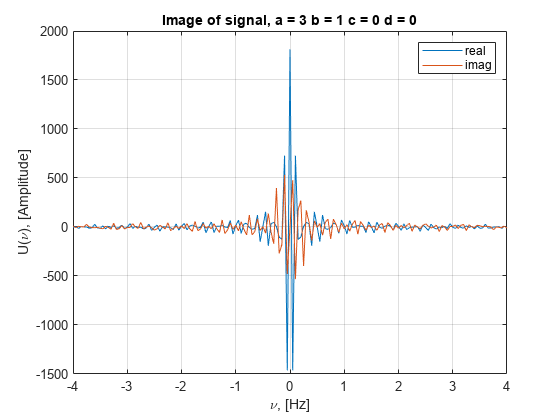

plotImage(1,t, t1,t2, a,b,c,d,  v)

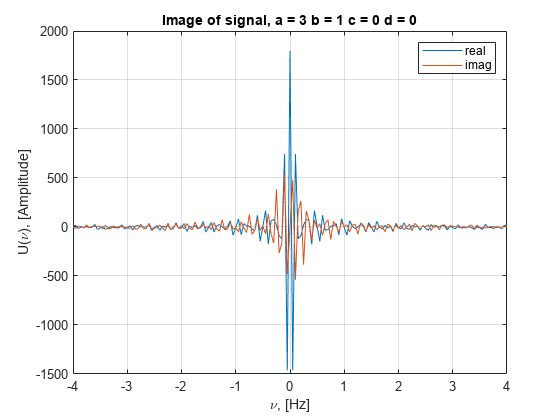

plotImage(1,t, t1,t2, a,b,c,d,  v)

## Задание 1. Жёсткие фильтры

*Общий подход к заданию таков: находим Фурье-образ сигнала ****u****, после обнуляем его значения на некоторых (выбранных вами) диапазонах частот, затем восстанавливаем сигнал с помощью обратного преобразования...*

### Убираем высокие частоты

Положите $c=0$

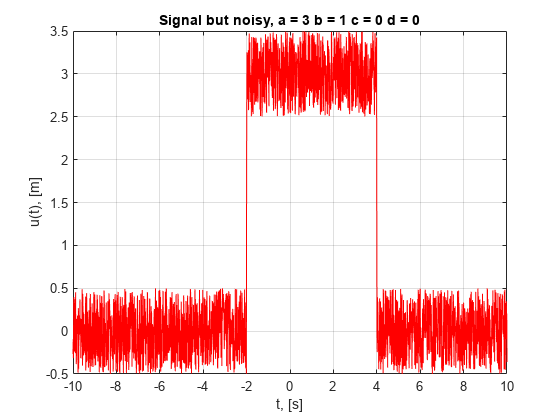

c=0; plotSignal(1, t, t1,t2, a,b,c ,d);

**Пусть наш сигнал начинается с нулевой секунды и длится до конца графика вправо**

Теперь найдём образ сигнала

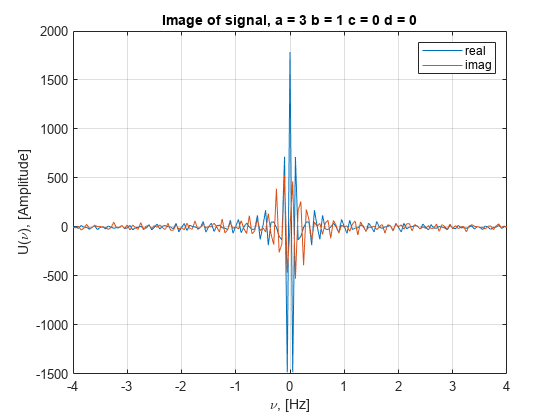

plotImage(1,t, t1,t2, a,b,c,d, v)

Оставим следующий диапазон низких частот $\left\lbrack -\nu_0 \;;\nu_0 \right\rbrack \to \left\lbrack -3;3\;\right\rbrack \;\textrm{Hz}$ , тогда для этого составим следующий фильтр

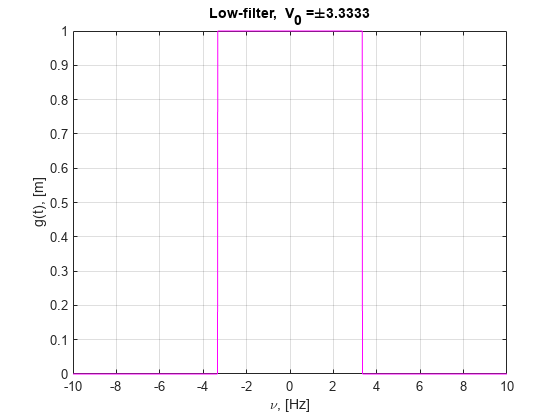

t1=-2; t2=2; V0 = T/6; plotFilter(1, t, V0,V1, a)

Тогда применим этот фильтр:

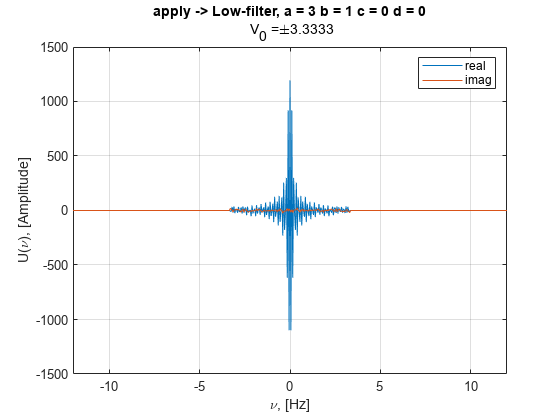

applyFilter(1, t, t1,t2, a,b,c,d, v, V0, V1)

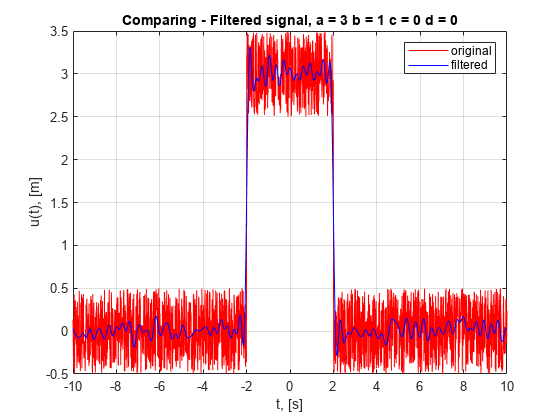

plotPure(1, t, t1,t2, a,b,c,d, v, V0, V1)

Проведём исследование на зависимость всего от параметра $b$ и от частоты среза $\nu_0$


$$b=1\;\;\;\;\;\;\;\;\;\;\;\;\;\;;{\;\;\;\;\;\;\;\;\;\;\;\;\;\;\nu }_0 =\left\lbrack -\frac{1}{2}\;;\frac{1}{2}\right\rbrack$$
 

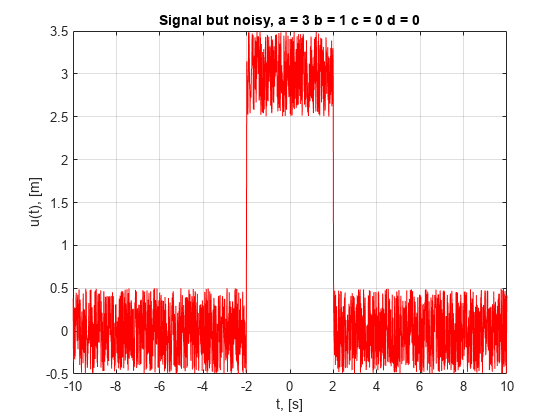

b=1; c=0; t1=-2; t2=2; V0 = 1/2;
plotSignal(1, t, t1,t2, a,b,c,d);

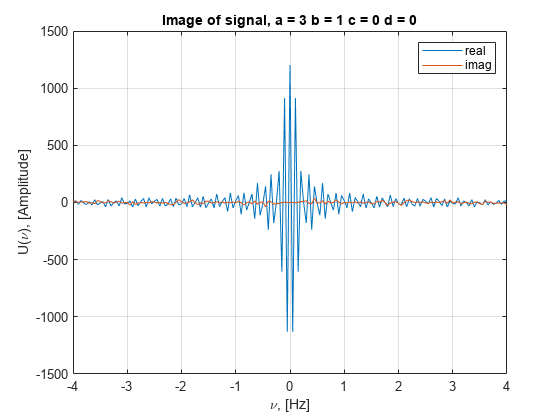

plotImage(1,t, t1,t2, a,b,c,d, v);

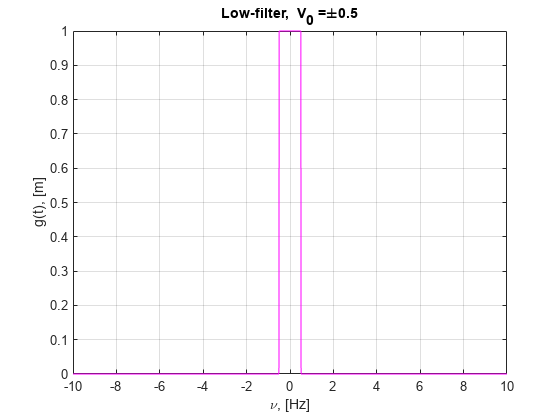

plotFilter(1, t, V0,V1, a);

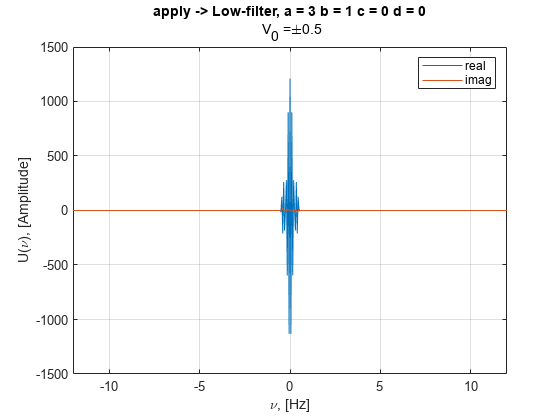

applyFilter(1, t, t1,t2, a,b,c,d, v, V0, V1)

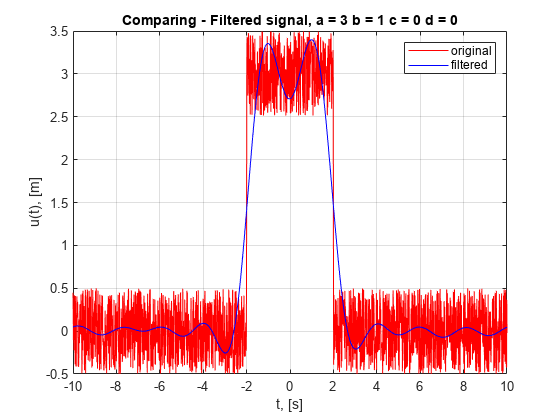

plotPure(1, t, t1,t2, a,b,c,d, v, V0, V1)


$$b=1\;\;\;\;\;\;\;\;\;\;\;\;\;;{\;\;\;\;\;\;\;\;\;\;\;\;\;\;\nu }_0 =\left\lbrack -5\;;5\right\rbrack$$
 

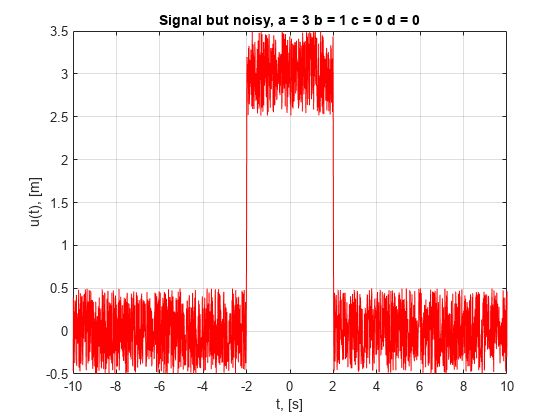

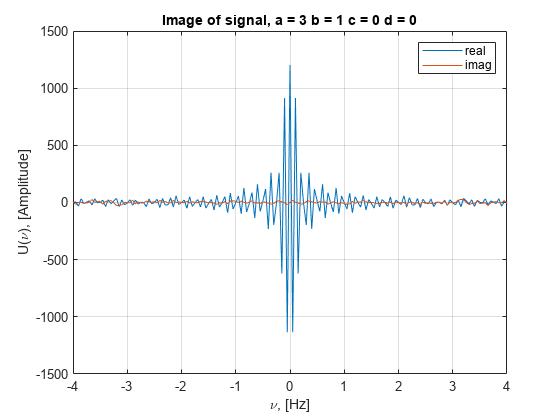

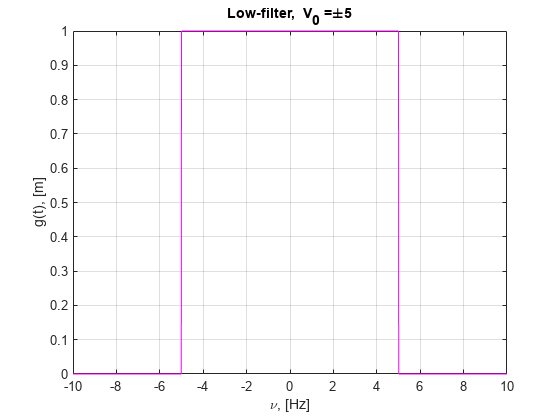

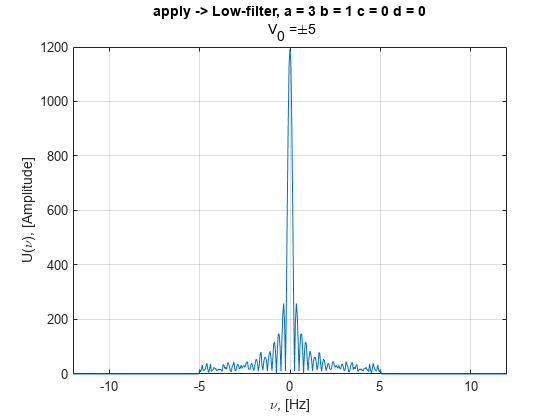

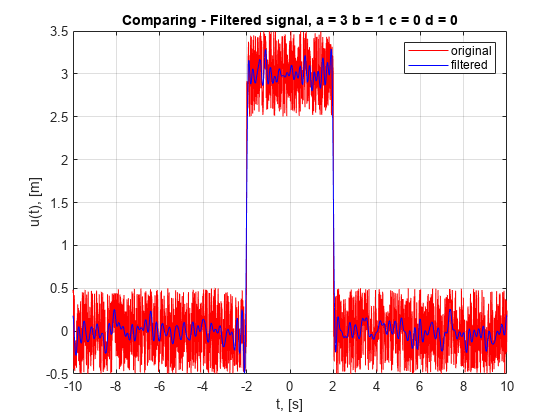

b=1; c=0; t1=-2; t2=2; V0 = 5;
analysis1(1, t, t1,t2, a,b,c,d, v, V0, V1) 


$$b=6\;\;\;\;\;\;\;\;\;\;\;\;\;\;;{\;\;\;\;\;\;\;\;\;\;\;\;\;\;\nu }_0 =\left\lbrack -\frac{1}{2};\frac{1}{2}\right\rbrack$$
 

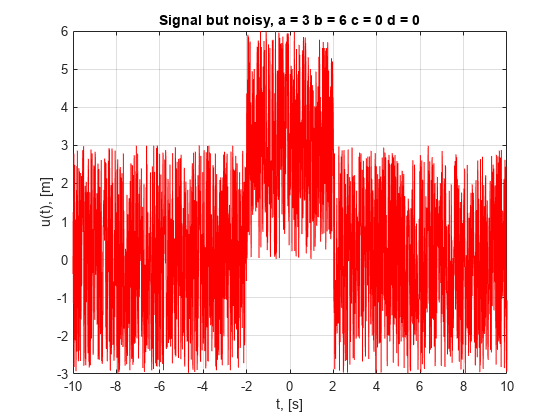

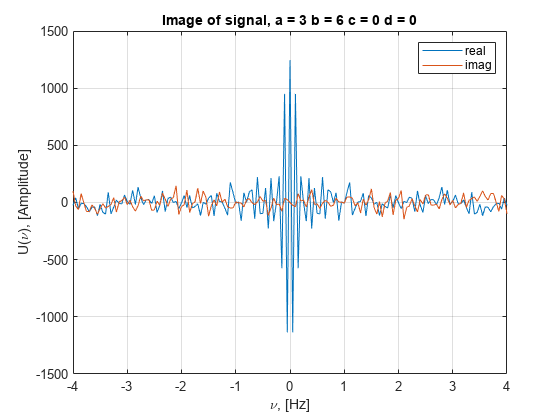

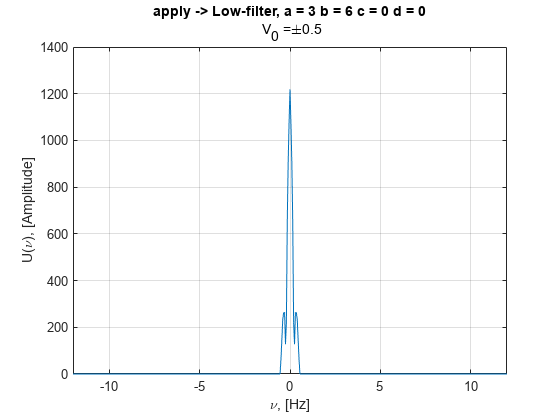

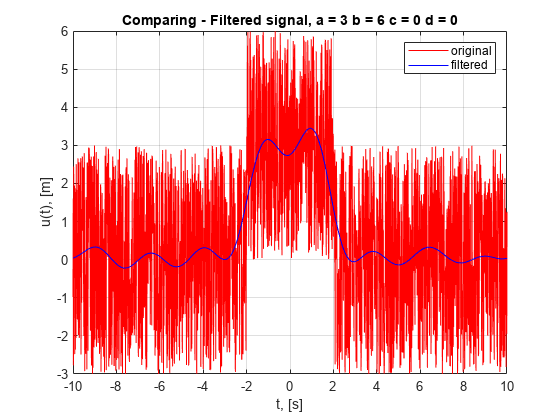

b=6; c=0; t1=-2; t2=2; V0 = 1/2;
analysis1(1, t, t1,t2, a,b,c,d, v, V0, V1)


$$b=6\;\;\;\;\;\;\;\;\;\;\;\;\;;{\;\;\;\;\;\;\;\;\;\;\;\;\;\;\nu }_0 =\left\lbrack -5\;;5\right\rbrack$$
 

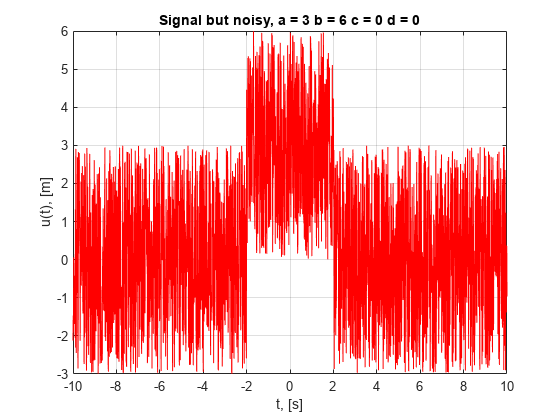

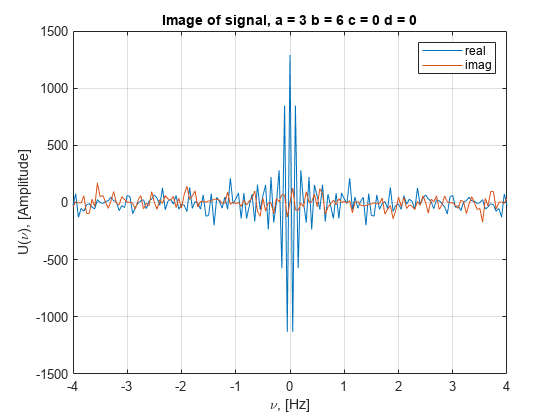

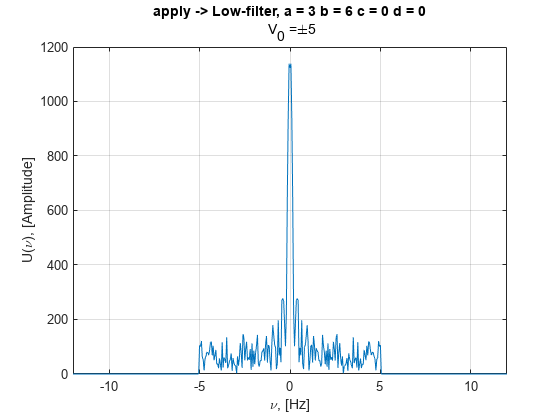

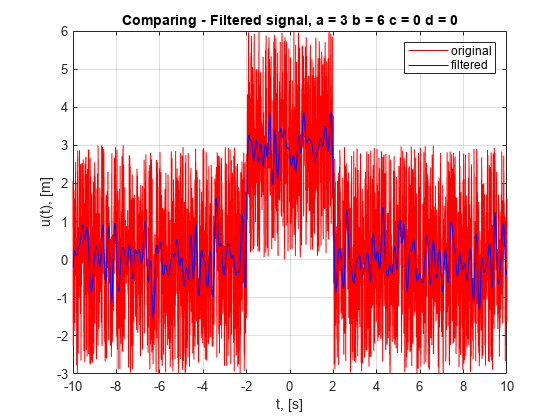

b=6; c=0; t1=-2; t2=2; V0 = 5;
analysis1(1, t, t1,t2, a,b,c,d, v, V0, V1)

#### Небольшие выводы по исследованию

При увеличении $b$ мы добавляем больше сбвига амплитуд в исходную синусоиду, что усложняет дальнешую фильтрацию и возвращение к исходной функции, поэтому при фильтрации с бОльшой $b$ очищенная функция была "неуверена" в себе. Также очевидно, при большем диапазоне фильтра мы оставляем больше частот, а значит и отфильтрованная функция будет больше колебаться, т.е. опять "неуверена" в себе. Поэтому оптимальный случай для фильтрации таким фильтром - небольшой $b$ и небольшой срез.

### Убираем специфические частоты

**1 испытание**

**V0, V1 - границы специфического фильтра, V2 - граница высокого фильтра**

% b=1;c=2;d=2; t1=-2; t2=2; V0 = 0.25; V1 = 0.5; V2 = 2;
% analysis2(2, t, t1,t2, a,b,c,d, v, V0, V1, V2)

**2 испытание**

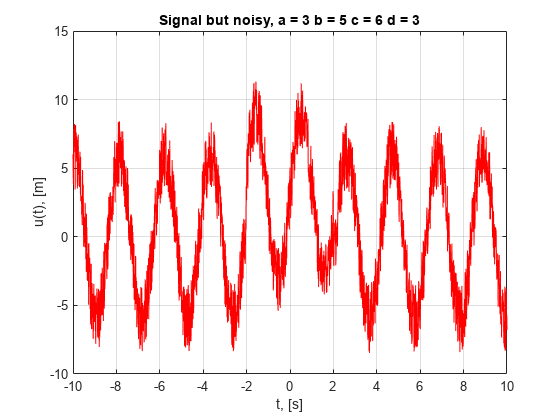

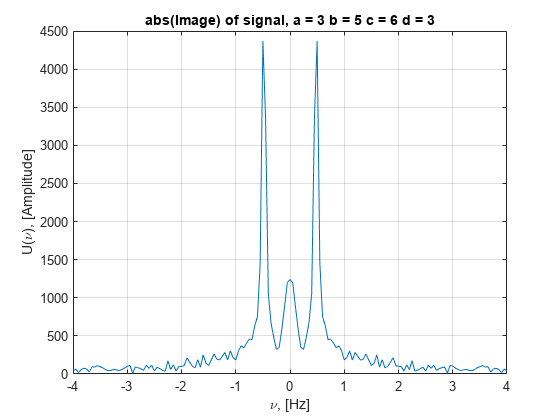

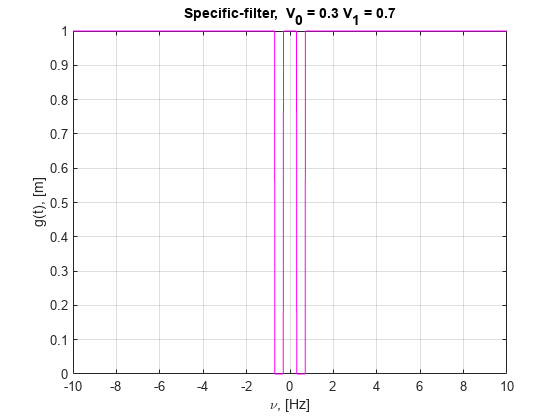

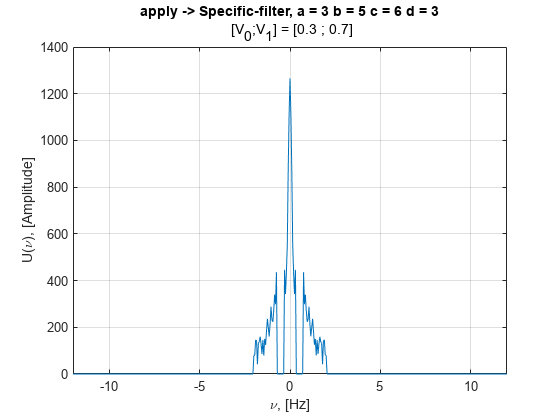

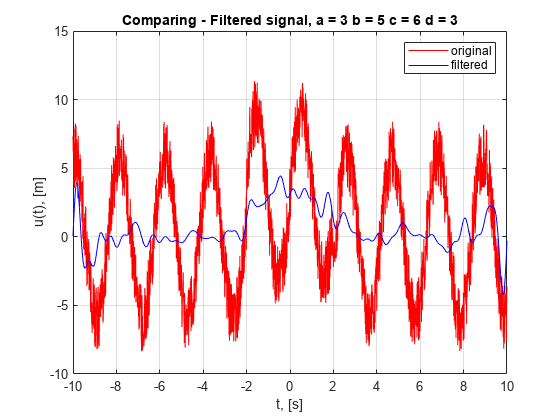

b=5;c=6;d=3; t1=-2; t2=2; V0 = 0.3; V1 = 0.7; V2 = 2;
analysis2(2, t, t1,t2, a,b,c,d, v, V0, V1, V2)

**3 испытание**

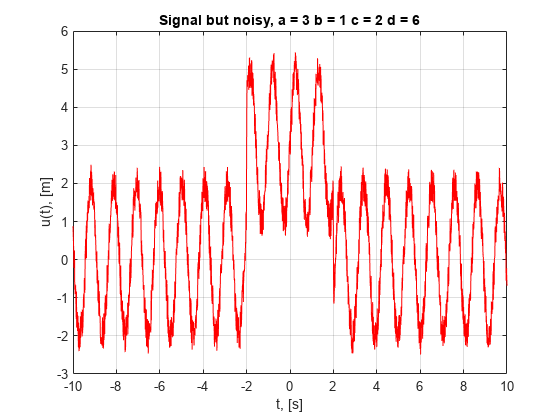

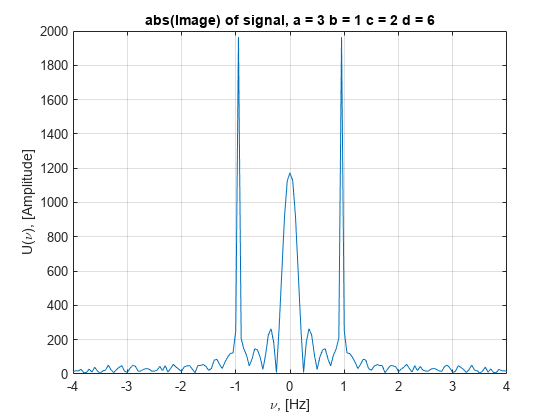

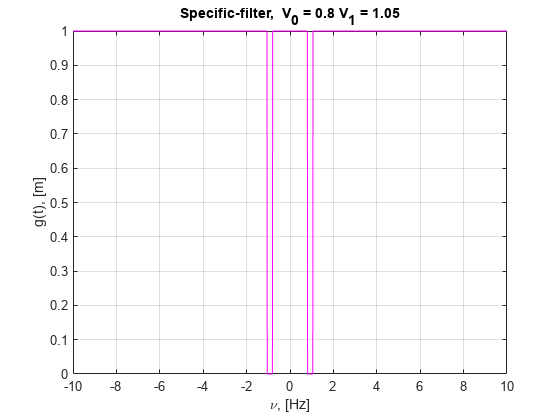

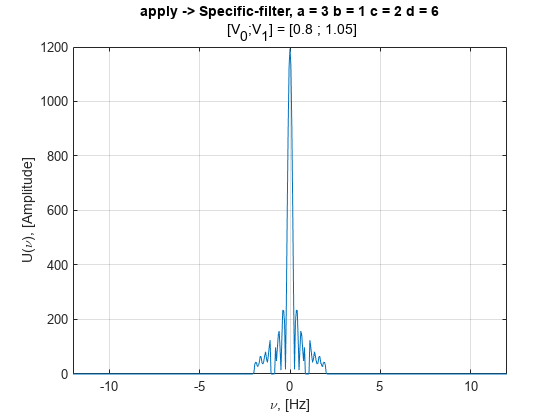

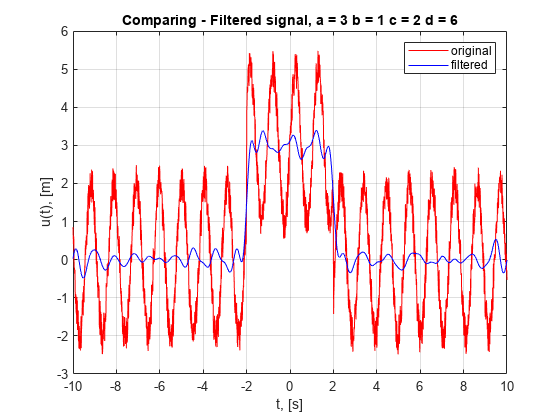

b=1;c=2;d=6; t1=-2; t2=2; V0 = 0.8; V1 = 1.05;  V2 = 2;
analysis2(2, t, t1,t2, a,b,c,d, v, V0, V1, V2)

**4 испытание**

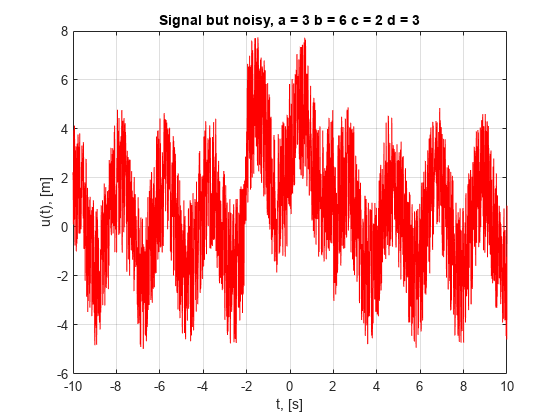

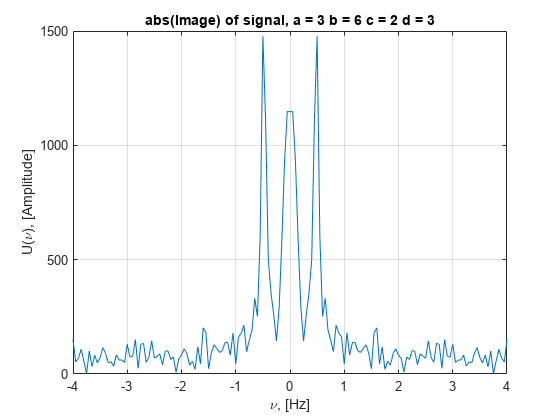

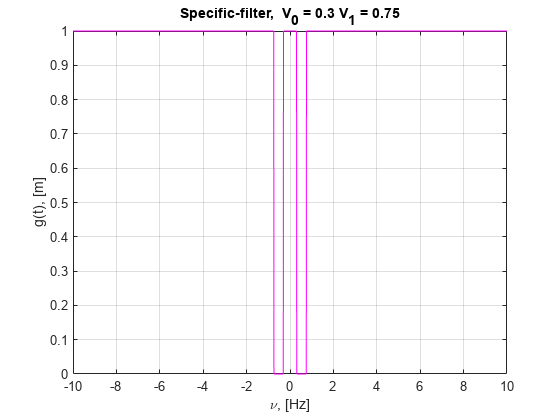

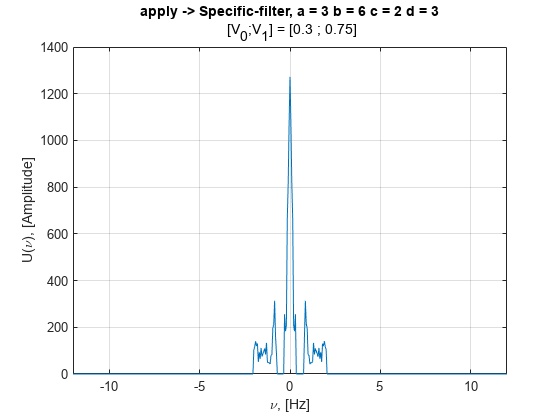

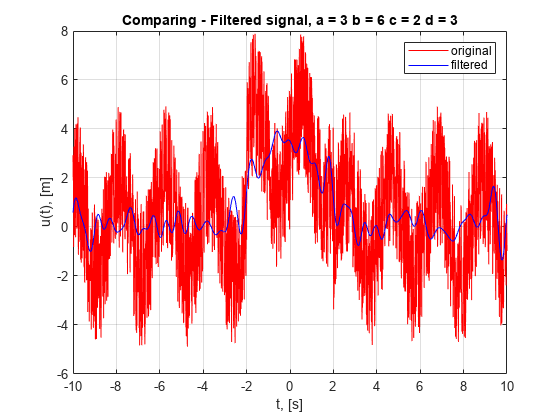

b=6;c=2;d=3; t1=-2; t2=2; V0 = 0.3; V1 = 0.75;  V2 = 2;
analysis2(2, t, t1,t2, a,b,c,d, v, V0, V1, V2)

**5 испытание --> отдельный случай, b=0**

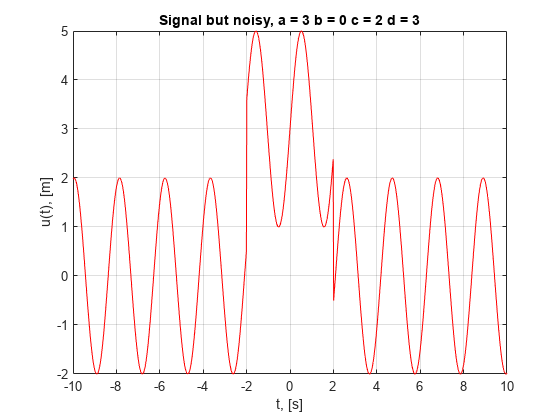

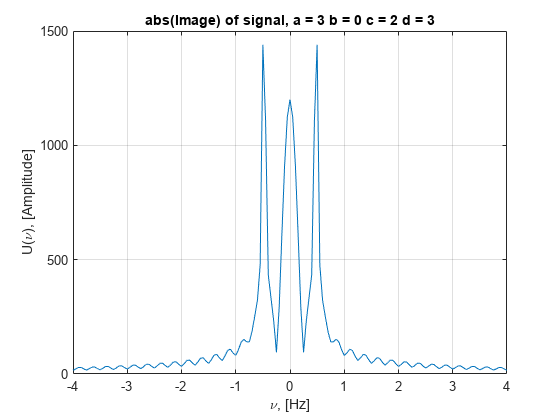

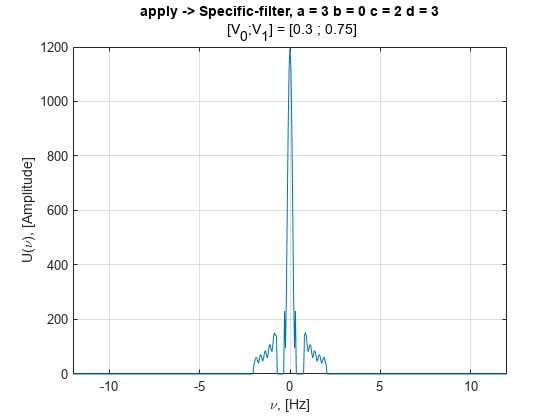

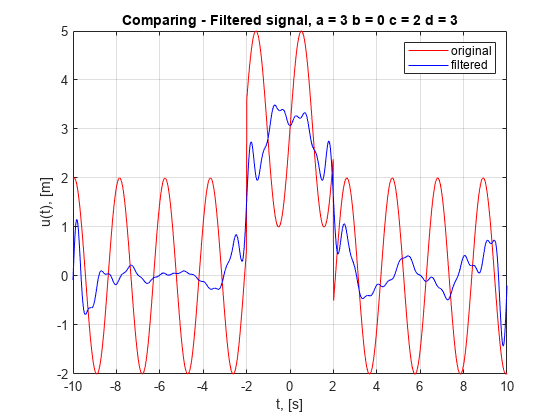

b=0;c=2;d=3; t1=-2; t2=2; V0 = 0.3; V1 = 0.75;  V2 = 2;
analysis2(2, t, t1,t2, a,b,c,d, v, V0, V1, V2)

Испытание 6 - добиваем

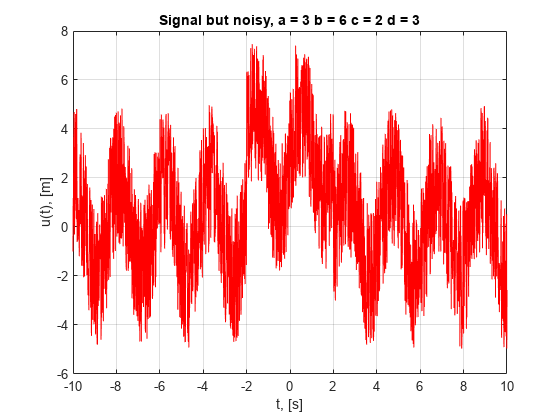

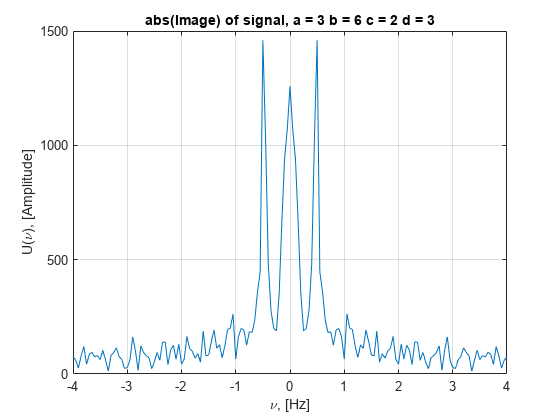

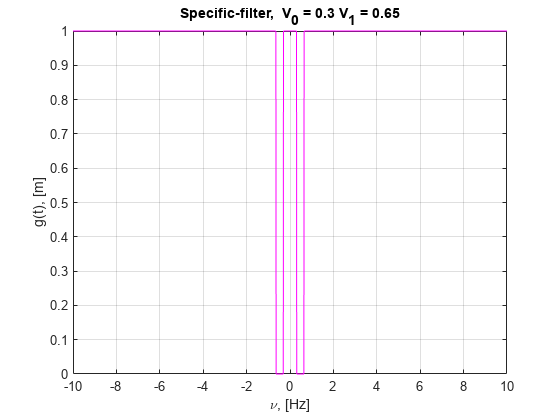

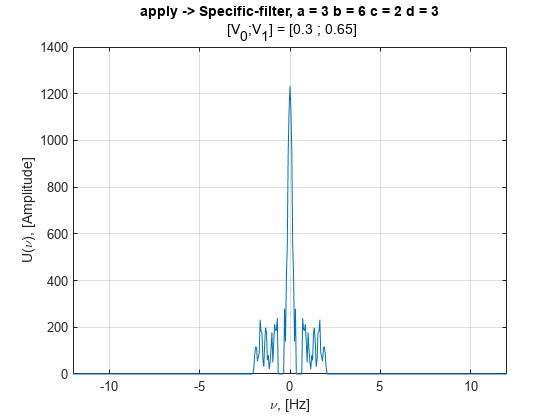

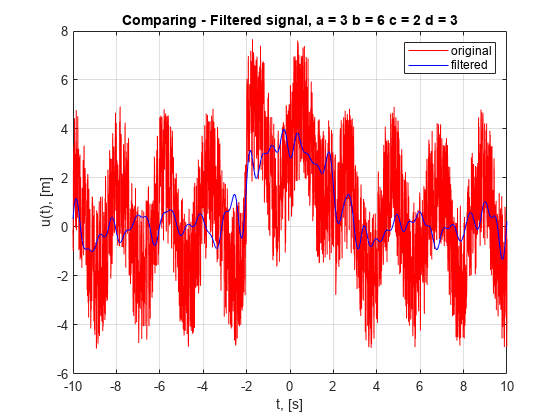

b=6;c=2;d=3; t1=-2; t2=2; V0 = 0.3; V1 = 0.65;  V2 = 2;
analysis2(2, t, t1,t2, a,b,c,d, v, V0, V1, V2)

#### Небольшие выводы по исследованию

Очевидно, что, чем меньше шума было внесено в функцию, тем лучше будет получаться его убрать. Но даже при довольно больших значениях параметров 𝑏, 𝑐, 𝑑 удалось убрать шум, не сильно исказив исходную функцию. И так получилось, что только срезав достаточно низких частот, мы хорошо приближаемся к исходной гладкой функции

### Убираем низкие частоты

**1 испытание**

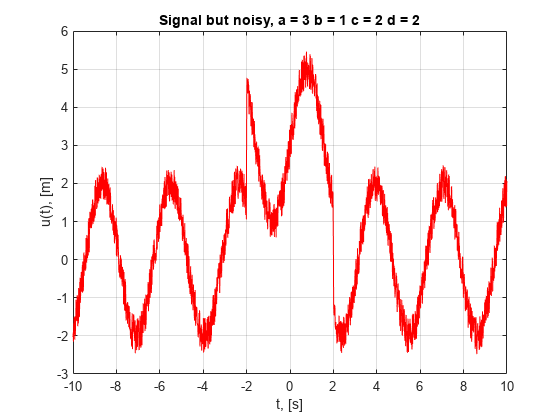

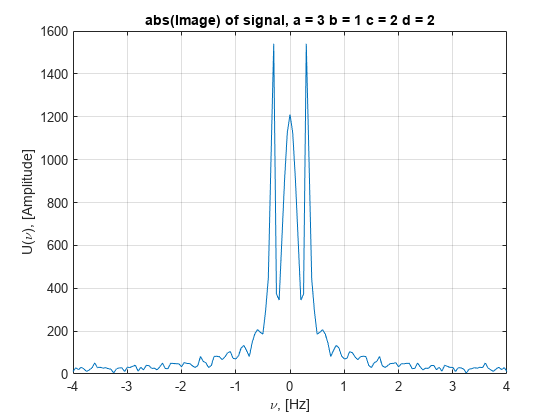

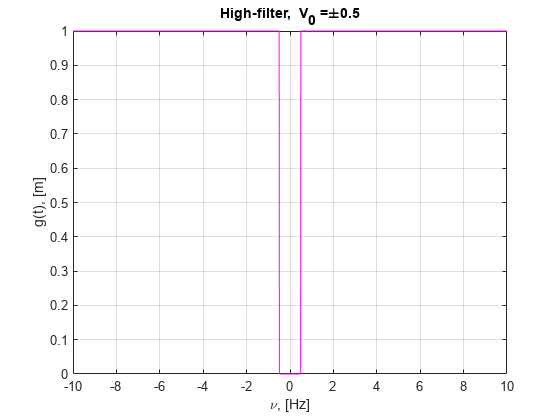

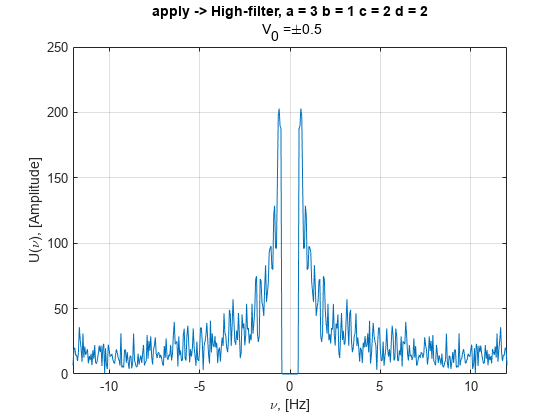

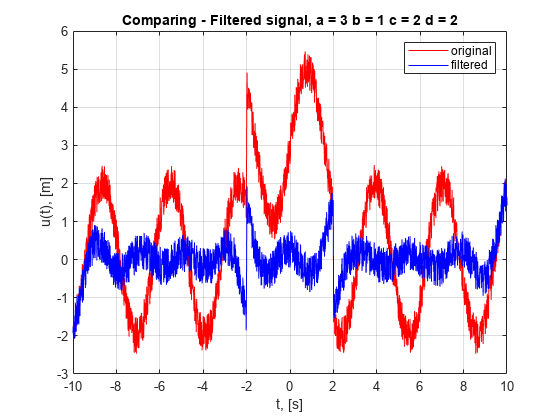

b=1;c=2;d=2; t1=-2; t2=2; V0 = 1/2; V1 = 3;
analysis3(3, t, t1,t2, a,b,c,d, v, V0, V1)

**2 испытание**

b=1;c=1;d=1; t1=-2; t2=2; V0 = 1/2

V0 = 0.5000

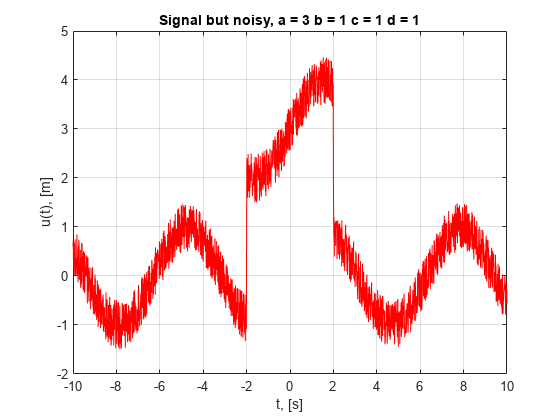

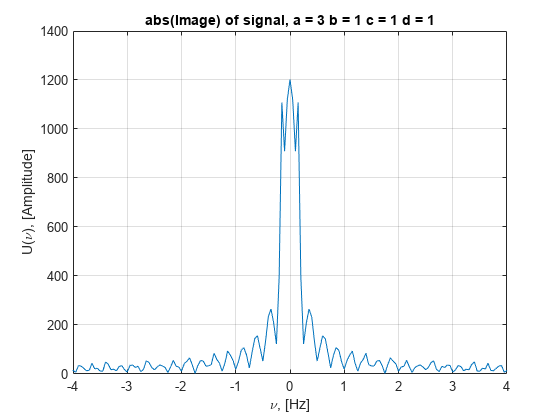

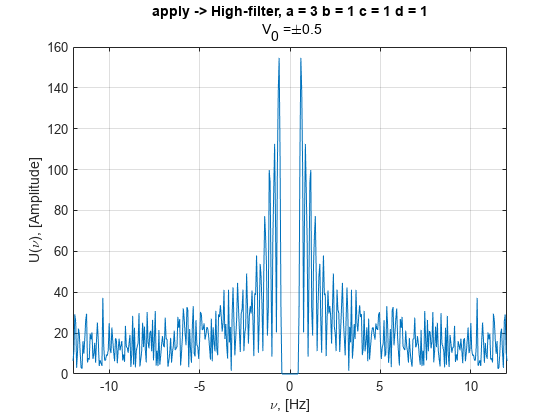

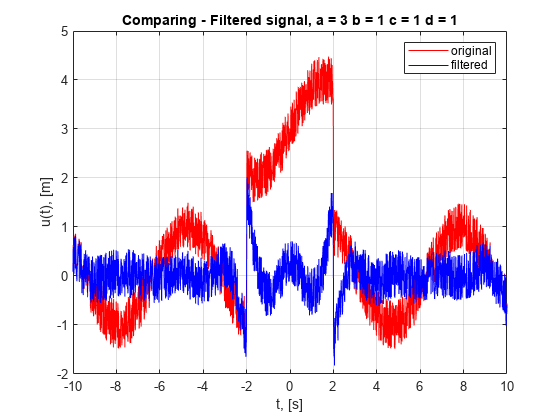

analysis3(3, t, t1,t2, a,b,c,d, v, V0, V1)

**3 испытание**

b=3;c=2;d=1; t1=-2; t2=2; V0 = 3

V0 = 3

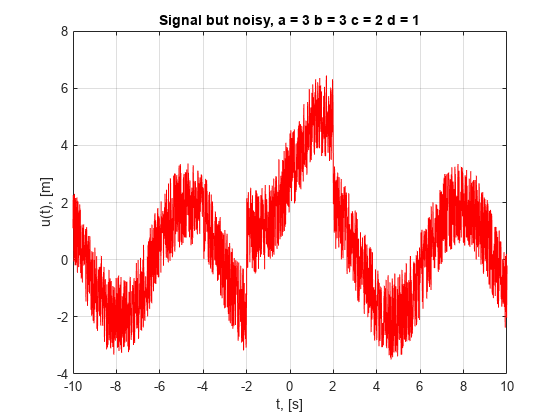

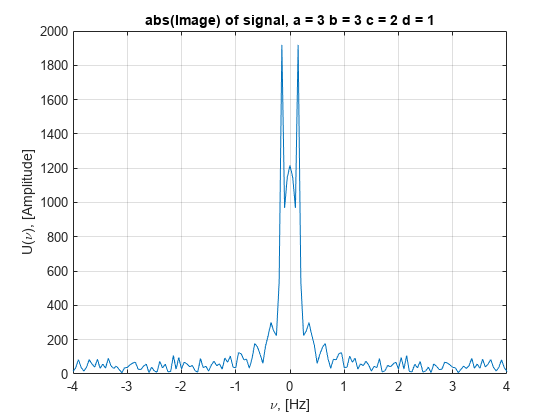

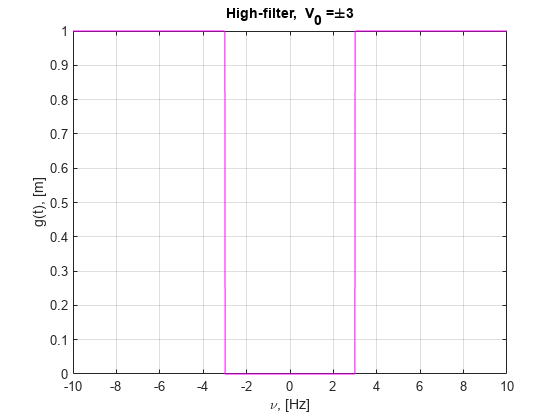

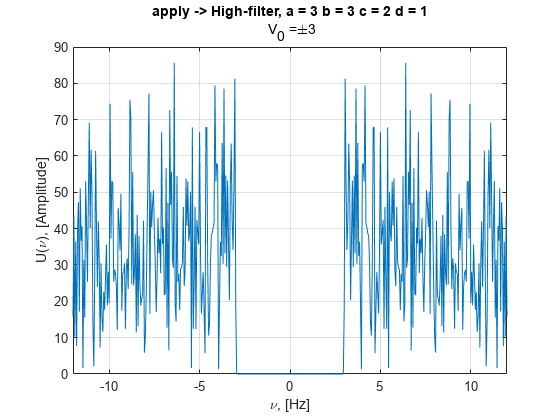

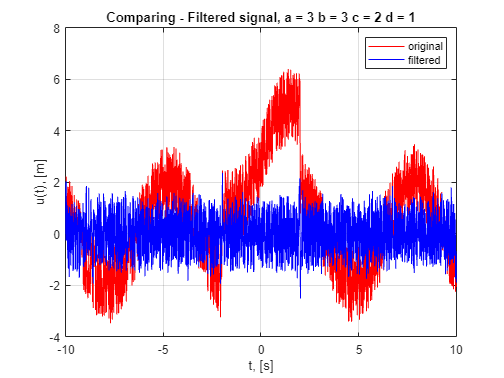

analysis3(3, t, t1,t2, a,b,c,d, v, V0, V1)

**4 испытание**

b=3;c=3;d=3; t1=-2; t2=2; V0 = 3

V0 = 3

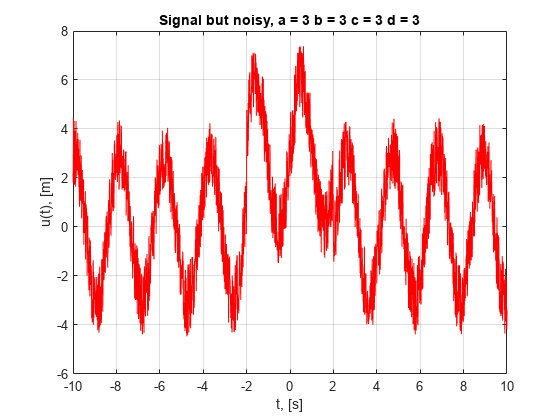

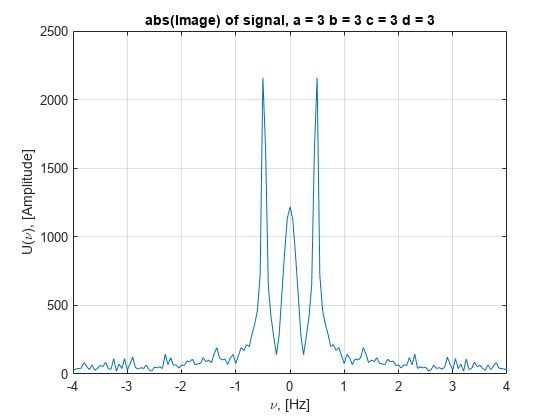

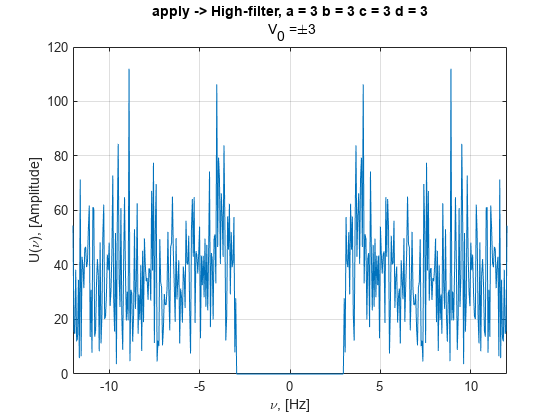

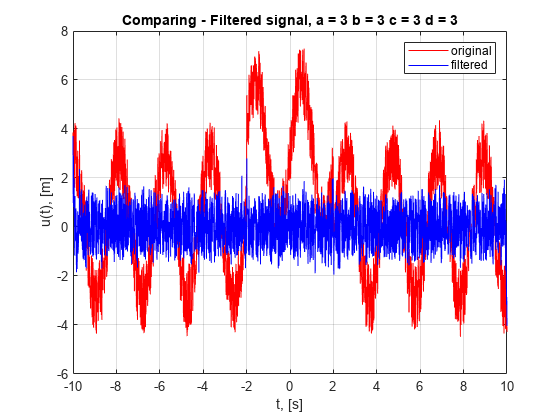

analysis3(3, t, t1,t2, a,b,c,d, v, V0, V1)

**5 испытание --> отдельный случай, b=0**

b=0;c=3;d=3; t1=-2; t2=2; V0 = 1/2

V0 = 0.5000

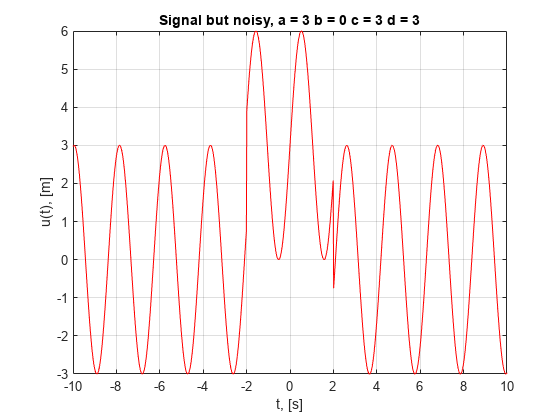

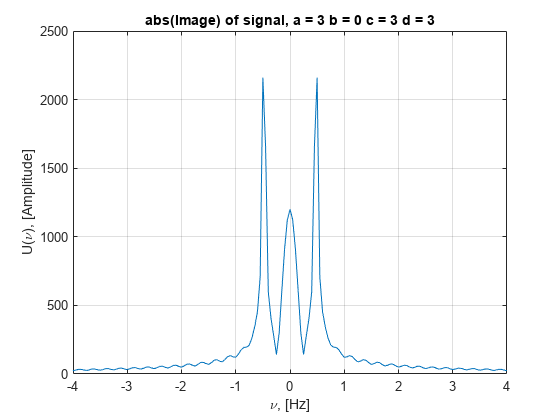

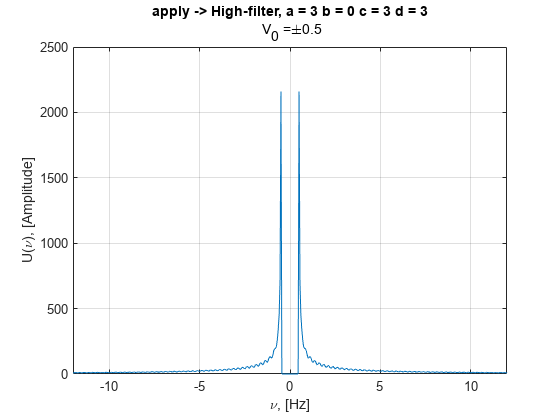

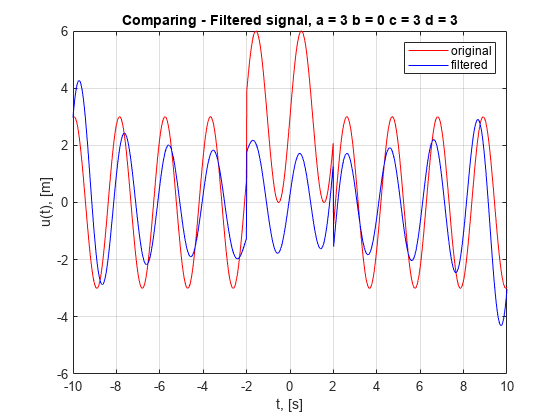

analysis3(3, t, t1,t2, a,b,c,d, v, V0, V1)

Испытание 6 - добиваем

b=6;c=5;d=4; t1=-2; t2=2; V0 = 1/9

V0 = 0.1111

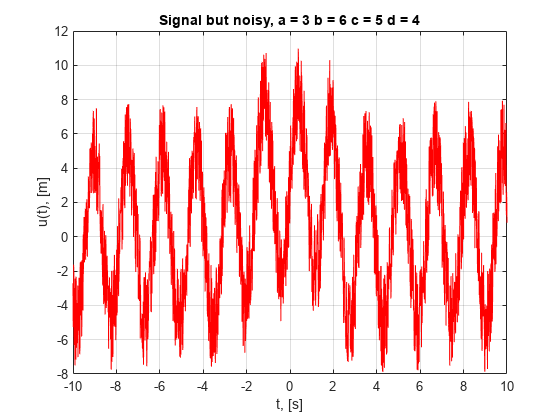

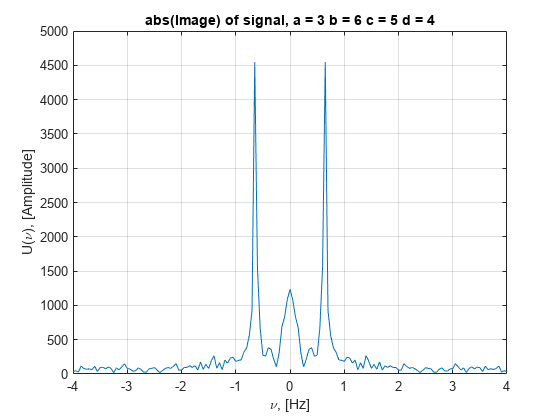

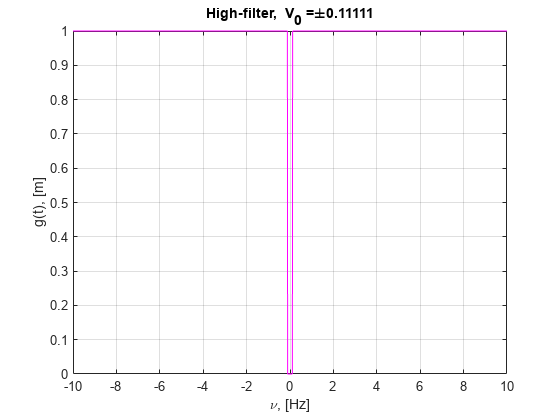

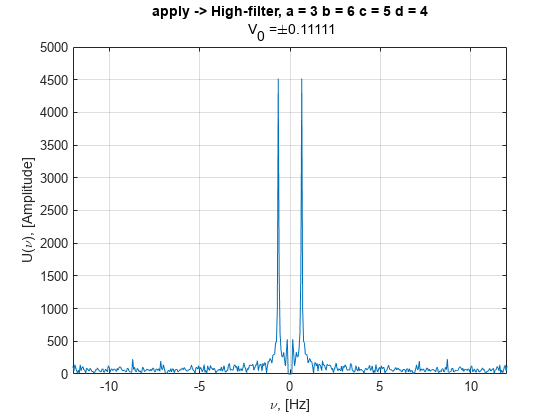

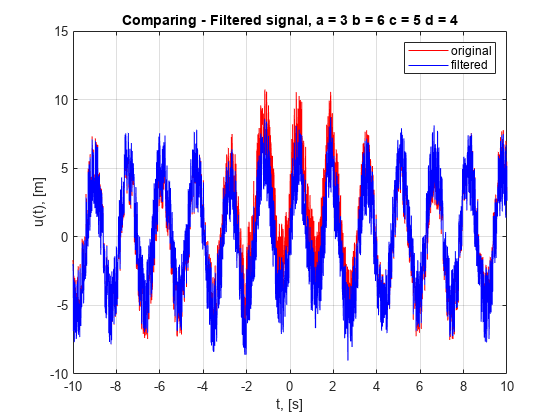

analysis3(3, t, t1,t2, a,b,c,d, v, V0, V1)

#### Небольшие выводы по исследованию

Видно, что от исходной функции остался только шум, и это логично, ведь мы убрали низкие частоты, которые, в большинстве, и соответствовали самой функции. Амплитуда шума осталась неизменной, что ещё раз подтверждает нашу гипотезу. Однако, если взять слишком малый срез, то функция почти будет подобать оригинальной 

##  Все функции, используемые в скрипте

### Первое задание

***Вспомогательная функция для помех***

function y = g(t, a, t1, t2)
    y = a * (heaviside(t - t1) - heaviside(t - t2));
end

**Фильтр высоких частот**

function y = g_inv(v, V0)
      y = ones(size(v));
      y((v < V0)&(v >= 0)) = 0;
      y((v > -V0)&(v <= 0)) = 0;
end 

**Фильтр специфических частот**

% inversed !!!
function y = g_even(v, V0, V1)
      y = ones(size(v));
      y( (v > 0) & ( (v >= V0)&(v <= V1) )) = 0;
      y( (v < 0) & ( (v < -V0)&(v > -V1) )) = 0;
end

**Фильтр низких частот**

function y = g_odd(v, V0)
%     y = (heaviside(t + V0) - heaviside(t - V0));
      y = ones(size(v));
      y((v > V0)&(v >= 0)) = 0;
      y((v < -V0)&(v <= 0)) = 0;

end

Функция для построения графика **фильтра **

function plotFilter(select, v, V0,V1, a)
    figure( randi([1 3000],1,1) )

     if (select == 1)
        g_t = g_odd(v, V0);
        task = "task_1_";
    elseif (select == 2)
        g_t = g_even(v, V0, V1);
        task = "task_2_";
    else
        g_t = g_inv(v, V0);
        task = "task_3_";
    end
    plot(v, g_t, 'magenta');

    if (select == 1)
        title("Low-filter, " + " V_0 =\pm"+V0)
        type = "Low-filter";
    elseif (select == 2)
        title("Specific-filter, " + " V_0 = "+V0+" V_1 = "+V1)
        type = "Specific-filter";
    else
        title("High-filter, " + " V_0 =\pm"+V0)
        type = "High-filter";
    end

    grid on
    xlabel('\nu, [Hz]');
    ylabel('g(t), [m]');
    hold off;
    
    path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab3\plotting';
    Name = task + "filter_a=" + a+"type ="+type;
    fullpath = fullfile(path, Name);
    saveas(gcf, fullpath, 'png');
end

Функция для построения графика сигнала

function plotSignal(select, t, t1,t2, a,b,c,d)
    figure( randi([1 3000],1,1) )
    u = g(t,a,t1,t2) + b*(rand(size(t))-0.5) + c*sin(d*t);
    
    if (select == 1)
        task = "task_1_";
    elseif (select == 2)
        task = "task_2_";
    else
        task = "task_3_";
    end

    plot(t, u, 'red');
    title("Signal but noisy, " + "a = "+a+" b = "+b+" c = "+c+" d = "+d)
    grid on;
%     xlim([t1, t2]);
    xlabel('t, [s]');
    ylabel('u(t), [m]');
    hold off;
    
    path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab3\plotting';
    Name = task + "signal_a=" + a+"_b="+b+"_c="+c+"_d="+d;
    fullpath = fullfile(path, Name);
    saveas(gcf, fullpath, 'png');
end

Функция для построения графика модуля образа сигнала

function plotAbsImage(select, t, t1,t2, a,b,c,d, v)
    figure( randi([1 3000],1,1) )
    u = g(t,a,t1,t2) + b*(rand(size(t))-0.5) + c*sin(d*t);
    U = fftshift(fft(u));
    
    if (select == 1)
        task = "task_1_";
    elseif (select == 2)
        task = "task_2_";
    else
        task = "task_3_";
    end

    plot(v, abs(U));
    xlim([-4; 4]);
    title("abs(Image) of signal, " + "a = "+a+" b = "+b+" c = "+c+" d = "+d)
    grid on;
    xlabel('\nu, [Hz]');
    ylabel('U(\nu), [Amplitude]');
    hold off;
    
    path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab3\plotting';
    Name = task+"abs_image_a=" + a+"_b="+b+"_c="+c+"_d="+d;
    fullpath = fullfile(path, Name);
    saveas(gcf, fullpath, 'png');
end

Функция для построения графика образа сигнала - вещественных и комплексных компонент

function plotImage(select, t, t1,t2, a,b,c,d, v)
    figure( randi([1 3000],1,1) )
    u = g(t,a,t1,t2) + b*(rand(size(t))-0.5) + c*sin(d*t);
    U = fftshift(fft(u));
    
     if (select == 1)
        task = "task_1_";
    elseif (select == 2)
        task = "task_2_";
     else
        task = "task_3_";
    end

    plot(v, real(U));
    hold on
    plot(v, imag(U));
    legend('real','imag')
    xlim([-4; 4]);
    title("Image of signal, " + "a = "+a+" b = "+b+" c = "+c+" d = "+d)
    grid on;
    xlabel('\nu, [Hz]');
    ylabel('U(\nu), [Amplitude]');
    hold off;
    
    path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab3\plotting';
    Name = task + "image_a=" + a+"_b="+b+"_c="+c+"_d="+d;
    fullpath = fullfile(path, Name);
    saveas(gcf, fullpath, 'png');
end

Функция для применение **фильтра** на образы сигнала - вещественное и комплексное

function applyFilter(select, t, t1,t2, a,b,c,d, v, V0, V1)
    figure( randi([1 3000],1,1) )

    u = g(t,a,t1,t2) + b*(rand(size(t))-0.5) + c*sin(d*t);
    U = fftshift(fft(u));
    
     if (select == 1)
        g_t = g_odd(v, V0);
        task = "task_1_";
    elseif (select == 2)
        g_t = g_even(v, V0, V1);
        task = "task_2_";
    else
        g_t = g_inv(v, V0);
        task = "task_3_";
     end

    plot(v, real(U).*g_t);
    hold on
    plot(v, imag(U).*g_t);
    legend('real','imag')
    xlim([-12; 12]);
    if (select == 1)
        title("apply -> Low-filter, " + "a = "+a+" b = "+b+" c = "+c+" d = "+d , {" V_0 =\pm"+V0})
    elseif (select == 2)
        title("apply -> Specific-filter, " + "a = "+a+" b = "+b+" c = "+c+" d = "+d , {" [V_0;V_1] = ["+V0+" ; "+V1+"]"})
    else
        title("apply -> High-filter, " + "a = "+a+" b = "+b+" c = "+c+" d = "+d , {" V_0 =\pm"+V0})
    end

    grid on;
    xlabel('\nu, [Hz]');
    ylabel('U(\nu), [Amplitude]');
    hold off;
    
    path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab3\plotting';
    Name = task+"applied_filter_a=" + a+"_b="+b+"_c="+c+"_d="+d;
    fullpath = fullfile(path, Name);
    saveas(gcf, fullpath, 'png');
end


Функция для применение **фильтра** на модуль образа сигнала 

function applyFilter2(select, t, t1,t2, a,b,c,d, v, V0, V1)
    figure( randi([1 3000],1,1) )

    u = g(t,a,t1,t2) + b*(rand(size(t))-0.5) + c*sin(d*t);
    U = fftshift(fft(u));
    
     if (select == 1)
        g_t = g_odd(v, V0);
        task = "task_1_";
    elseif (select == 2)
        g_t = g_even(v, V0, V1);
        task = "task_2_";
    else
        g_t = g_inv(v, V0);
        task = "task_3_";
    end
    
    plot(v, abs(U).*g_t);
    xlim([-12; 12]);
    if (select == 1)
        title("apply -> Low-filter, " + "a = "+a+" b = "+b+" c = "+c+" d = "+d , {" V_0 =\pm"+V0})
    elseif (select == 2)
        title("apply -> Specific-filter, " + "a = "+a+" b = "+b+" c = "+c+" d = "+d , {" [V_0;V_1] = ["+V0+" ; "+V1+"]"})
    else
        title("apply -> High-filter, " + "a = "+a+" b = "+b+" c = "+c+" d = "+d , {" V_0 =\pm"+V0})
    end

    grid on;
    xlabel('\nu, [Hz]');
    ylabel('U(\nu), [Amplitude]');
    hold off;
    
    path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab3\plotting';
    Name = task+"applied_filter_a=" + a+"_b="+b+"_c="+c+"_d="+d;
    fullpath = fullfile(path, Name);
    saveas(gcf, fullpath, 'png');
end


Функция для применение двух фильтров -- сначала специфический, потом низкий

function applyFilter3(select, t, t1,t2, a,b,c,d, v, V0, V1, V2)
    figure( randi([1 3000],1,1) )

    u = g(t,a,t1,t2) + b*(rand(size(t))-0.5) + c*sin(d*t);
    U = fftshift(fft(u));
    
     
    g_t1 = g_odd(v, V2);


    g_t2 = g_even(v, V0, V1);
    task = "task_2_";
    
    plot(v, (abs(U).*g_t2).*g_t1);
    xlim([-12; 12]);
    if (select == 1)
        title("apply -> Low-filter, " + "a = "+a+" b = "+b+" c = "+c+" d = "+d , {" V_0 =\pm"+V0})
    elseif (select == 2)
        title("apply -> Specific-filter, " + "a = "+a+" b = "+b+" c = "+c+" d = "+d , {" [V_0;V_1] = ["+V0+" ; "+V1+"]"})
    else
        title("apply -> High-filter, " + "a = "+a+" b = "+b+" c = "+c+" d = "+d , {" V_0 =\pm"+V0})
    end

    grid on;
    xlabel('\nu, [Hz]');
    ylabel('U(\nu), [Amplitude]');
    hold off;
    
    path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab3\plotting';
    Name = task+"applied_filters_a=" + a+"_b="+b+"_c="+c+"_d="+d;
    fullpath = fullfile(path, Name);
    saveas(gcf, fullpath, 'png');
end

**Функция для отрисовка графика "чистого" сигнала после фильтрации**

function plotPure(select, t, t1,t2, a,b,c,d, v, V0, V1)
    figure( randi([1 3000],1,1) )
    u = g(t,a,t1,t2) + b*(rand(size(t))-0.5) + c*sin(d*t);
    U = fftshift(fft(u));
    
     if (select == 1)
        g_t = g_odd(v, V0);
        task = "task_1_";
    elseif (select == 2)
        g_t = g_even(v, V0, V1);
        task = "task_2_";
    else
        g_t = g_inv(v, V0);
        task = "task_3_";
    end

    pure = U.*g_t;
    u_new = ifft(ifftshift(pure)); % Обратное преобразование
    plot(t, u, 'red');
    hold on;
    plot(t, u_new, 'blue');
    title("Comparing - Filtered signal, " + "a = "+a+" b = "+b+" c = "+c+" d = "+d)
    legend('original', 'filtered')
    grid on

    xlabel('t, [s]');
    ylabel('u(t), [m]');
    hold off;
    
    path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab3\plotting';
    Name = task + "pure_signal_a=" + a+"_b="+b+"_c="+c+"_d="+d;
    fullpath = fullfile(path, Name);
    saveas(gcf, fullpath, 'png');
end


**Функция для отрисовка графика "чистого" сигнала после фильтрации - для второго случая только, потому что два фильтра применяем**

function plotPure2(select, t, t1,t2, a,b,c,d, v, V0, V1, V2)
    figure( randi([1 3000],1,1) )
    u = g(t,a,t1,t2) + b*(rand(size(t))-0.5) + c*sin(d*t);
    U = fftshift(fft(u));
    
    g_t1 = g_odd(v, V2);
    g_t2 = g_even(v, V0, V1);
    task = "task_2_";

    pure = (U.*g_t2).*g_t1;
    u_new = ifft(ifftshift(pure)); % Обратное преобразование
    plot(t, u, 'red');
    hold on;
    plot(t, u_new, 'blue');
    title("Comparing - Filtered signal, " + "a = "+a+" b = "+b+" c = "+c+" d = "+d)
    legend('original', 'filtered')
    grid on
    xlabel('t, [s]');
    ylabel('u(t), [m]');
    hold off;
    
    path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab3\plotting';
    Name = task + "pure_signal_a=" + a+"_b="+b+"_c="+c+"_d="+d;
    fullpath = fullfile(path, Name);
    saveas(gcf, fullpath, 'png');
end


*Мета-функция для быстрого анализа по первому заданию:*

function analysis1(select, t, t1,t2, a,b,c,d, v, V0, V1)
    plotSignal(select, t, t1,t2, a,b,c,d);
    plotImage(select,t, t1,t2, a,b,c,d, v);
    plotFilter(select, t, V0,V1, a);
    applyFilter2(select, t, t1,t2, a,b,c,d, v, V0, V1);
    plotPure(select, t, t1,t2, a,b,c,d, v, V0, V1);
end

*Мета-функция для быстрого анализа по второму заданию:*

function analysis2(select, t, t1,t2, a,b,c,d, v, V0, V1, V2)
    plotSignal(select, t, t1,t2, a,b,c,d);
    plotAbsImage(select,t, t1,t2, a,b,c,d, v);
    plotFilter(select, t, V0,V1, a);
    if (b==0)
        applyFilter2(select, t, t1,t2, a,b,c,d, v, V0, V1, V2);
    else
        applyFilter3(select, t, t1,t2, a,b,c,d, v, V0, V1, V2);
    end
    plotPure2(select, t, t1,t2, a,b,c,d, v, V0, V1, V2);
end


*Мета-функция для быстрого анализа по третьему заданию:*

function analysis3(select, t, t1,t2, a,b,c,d, v, V0, V1)
    plotSignal(select, t, t1,t2, a,b,c,d);
    plotAbsImage(select,t, t1,t2, a,b,c,d, v);
    plotFilter(select, t, V0,V1, a);
    applyFilter2(select, t, t1,t2, a,b,c,d, v, V0, V1);
    plotPure(select, t, t1,t2, a,b,c,d, v, V0, V1);
end